y=0.2;
a=0.2;
m=y*log(a)+(1-y)*log(1-a)

m =         -0.500402423538188


num=xlsread('./dataSet/offline.xlsx');
num=num';
x=[2,3,4,5,6;7,8,9,10,11];
y=[2,3;4,5];
num=mapminmax(num,0,1);
% X=num(:,1);
% Y=num(:,2);
X=0.01*randn(1500,1);
Y=X.^2;
coeff = corr(X , Y)

coeff =       -0.00480344333655432


coeff = corr(num' , num');
coeff = corr(coeff , coeff)

coeff =                          1         0.976736052620577        -0.883838691267966        -0.504424338855168         0.899940866738258       0.00338497910693722         0.854348888336515         0.661198956345401        -0.882609666520052         -0.89544300767755         0.858668603580088        -0.906264284880514        -0.598514248315229         0.963037924199678        -0.845914369367798        -0.925873500708338         0.873576635529865         0.952596138942368        -0.939078904796953        -0.371902700603325         0.743194104954324         0.323811468611052       -0.0309641506032486        -0.893870178935435        -0.831930629294191        -0.948312692326369         0.976613454163045          0.70790645003123        -0.627835514259534         0.723919391477193         0.972554144239724         0.883491823505948          0.56029479900242         0.916363961932689        -0.907148826028908         0.868931632154417        -0.948073578534585         0.976166690397451    

[x,xx]=eig(coeff);
xx

xx =           176.395512251015                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0       

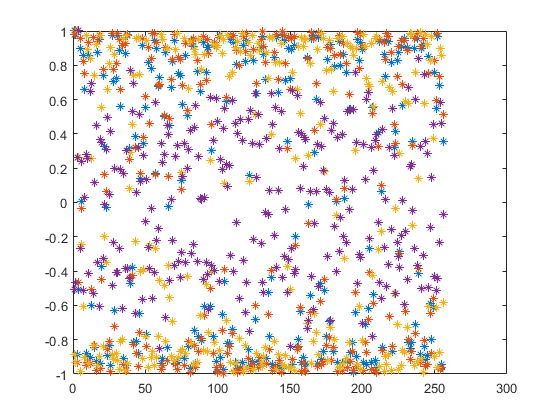

plot(coeff(1,:),'*')
hold on
plot(coeff(2,:),'*')
hold on
plot(coeff(3,:),'*')
hold on
plot(coeff(4,:),'*')

mean(coeff)

ans =        0.00847028028066252         0.012099242937913       -0.0237808131303406        0.0117649463891468        0.0209071019666756        0.0266569202090639       -0.0116308577997532        0.0334754019127063       -0.0205719765211662      -0.00935433093927704        0.0216721005549196      -0.00931191862463714         0.023528586100366       0.00160083148126897      -0.00165601776368261       -0.0113241041334538        0.0212346666798259        0.0107574528922127       -0.0205923714495132       -0.0288864894908175        0.0287697168224178       0.00780832100813559        0.0396511089024148       0.00867624712668105       -0.0145654851865147       -0.0107661251498802       0.00619458752105617        0.0328476912757172       -0.0342643451074723        0.0267137660279375       0.00935549010473776        0.0212733611090386         0.022040015920275      0.000226452996760239       -0.0182370773409198        0.0244669341748686       -0.0174087084390277        0.0121057242930495      

mean(std(coeff))

ans =          0.697609423562236
